Patient 2 Post Clinic Analysis Report 

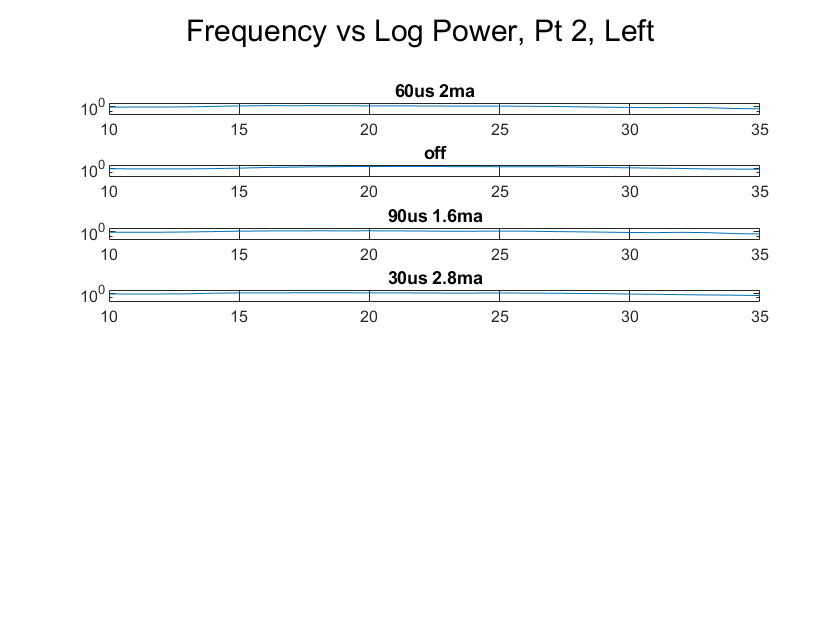

clear all;
%get the json 
% cd('C:\Users\sydne\Documents\github\perceive\patientData')
cd('C:\Users\sydne\Documents\Github\perceive\patientData\Patient2_0604')
%jsonFiles = 'Report_Json_Session_Report_20210604T120025.json'; 
jsonFiles = 'pt2_0604_rl_stream.json'; 
js = jsondecode(fileread(jsonFiles));
%set back to the correct directory 
% cd('C:\Users\sydne\Documents\github\perceive\postAnalysis') 
cd('C:\Users\sydne\Documents\Github\perceive\postAnalysis')

%just hard coding that the first four in the brainsenselfp are for the left
%and the last four are for the right...I think! 

%% create a struct of the relevant data from brainsense 
leng = numel(js.BrainSenseLfp);
data = struct;
for i=1:4
    x = num2str(i);
    field = append("treatment", x);
    data.(field).channel = js.BrainSenseLfp(i).Channel;
    data.(field).time = datetime(replace({js.BrainSenseLfp(i).FirstPacketDateTime}, {'T', 'Z'},  {' ', ''}));
    data.(field).pw = js.BrainSenseLfp(i).TherapySnapshot.Left.PulseWidthInMicroSecond;
    data.(field).ma = js.BrainSenseLfp(i).TherapySnapshot.Left.LowerLimitInMilliAmps;
    data.(field).timeDomain = js.BrainSenseTimeDomain(i).TimeDomainData;
end

%get legend info 
%some parts must be hard coded bc 
for i = 1:4 
    x = num2str(i);
    field = append("treatment", x);
    pw = num2str(data.(field).pw); 
    ma = num2str(data.(field).ma);
    legendVal{i} = ((append(pw, "us ", ma, "ma")));
end 
legendVal{2} = "off";
legendVal{5} = "entry";

%% do pwelch on the LFP recording
%uncomment the subplot lines to just create a 5x1 subplot 
fs=250;
nfft=250;
window=250;
overlap=150;
%subplot(leng, 1, 1)
for i=1:4
    %make i usable for indexing into the struct 
    x = num2str(i);
    field = append("treatment", x);
    %calculate values
    t = data.(field).timeDomain;
    [pxx,f] = pwelch(t,window,overlap,nfft,fs);
    data.(field).LFPpower = pxx;
    data.(field).freq = f;
    fbeta = f > 12 & f < 33; 
    data.(field).avg = mean(pxx(fbeta));
    
    subplot(leng, 1, i)
    semilogy(f,sqrt(pxx))
    xlim([10 35])
    ylim([0 5])
    title(legendVal{i})
    hold on
end
sgtitle('Frequency vs Log Power, Pt 2, Left') 



for i = 1:4 
    x = num2str(i);
    field = append("treatment", x);
    means(i) = data.(field).avg;
end 

Tmean = array2table(means', 'VariableNames', {'Average Power in Beta Region (mV)'});
Tname = cell2table(legendVal', 'VariableNames', {'Treatment'}); 
tbl = [Tname Tmean];

All tables being horizontally concatenated must have the same number of rows.

sortrows(tbl, {'Average Power in Beta Region (mV)'}, 'descend')

Right Side 

clear all;
%get the json 
cd('C:\Users\sydne\Documents\github\perceive\patientData')
jsonFiles = 'Report_Json_Session_Report_20210604T120025.json'; 
js = jsondecode(fileread(jsonFiles));
%set back to the correct directory 
cd('C:\Users\sydne\Documents\github\perceive\postAnalysis') 

%just hard coding that the first four in the brainsenselfp are for the left
%and the last four are for the right...I think!  

%check stimulation field js brain sense lfp>>lfp data >> left or right
%snapshot
figure;
leng = numel(js.BrainSenseLfp);
data = struct;
for i=5:8
    x = num2str(i);
    field = append("treatment", x);
    data.(field).channel = js.BrainSenseLfp(i).Channel;
    data.(field).time = datetime(replace({js.BrainSenseLfp(i).FirstPacketDateTime}, {'T', 'Z'},  {' ', ''}));
    data.(field).pw = js.BrainSenseLfp(i).TherapySnapshot.Right.PulseWidthInMicroSecond;
    data.(field).ma = js.BrainSenseLfp(i).TherapySnapshot.Right.LowerLimitInMilliAmps;
    data.(field).timeDomain = js.BrainSenseTimeDomain(i).TimeDomainData;
end 

%get legend info 
%some parts must be hard coded bc 
for i=1:4
    x = num2str(i+4);
    field = append("treatment", x);
    pw = num2str(data.(field).pw); 
    ma = num2str(data.(field).ma);
    legendVal{i} = ((append(pw, "us ", ma, "ma")));
end 
%need to investigate discrepency between json and pdf summary
legendVal{3} = "off or entry";
%legendVal{5} = "entry";
 
%% do pwelch on the LFP recording
%uncomment the subplot lines to just create a 5x1 subplot 
fs=250;
nfft=250;
window=250;
overlap=150;
subplot(4, 1, 1)
for i=5:8
    %make i usable for indexing into the struct 
    y = i-4; 
    x = num2str(i);
    field = append("treatment", x);
    %calculate values
    t = data.(field).timeDomain;
    [pxx,f] = pwelch(t,window,overlap,nfft,fs);
    data.(field).LFPpower = pxx;
    data.(field).freq = f;
    fbeta = f > 12 & f < 33; 
    data.(field).avg = mean(pxx(fbeta));
    
    subplot(4, 1, y)
    semilogy(f,sqrt(pxx))
    xlim([10 35])
    ylim([0 5])
    title(legendVal(y))
    hold on
end
sgtitle('Frequency vs Log Power, Pt 2, Right') 

for i=1:4
    x = num2str(i+4);
    field = append("treatment", x);
    means(i) = data.(field).avg;
end 

Tmean = array2table(means', 'VariableNames', {'Average Power in Beta Region (mV)'});
Tname = cell2table(legendVal', 'VariableNames', {'Treatment'}); 
tbl = [Tname Tmean];
sortrows(tbl, {'Average Power in Beta Region (mV)'}, 'descend')
